# Interpolazione

L’interpolazione consiste nel trovare un polinomio che “approssima” un’altra funzione o “interpola” dei dati. 

Nella pratica: dato un certo numero di punti, cerco un polinomio di un certo grado che passa per quei punti.

## Polyfit (var x, var y, grado n)

% p = polyfit(x, y, n);

Restituisce i coefficienti di un polinomio che costituisce il miglior adattamento *nel senso dei minimi quadrati* per i dati in `y`. I coefficienti in `p` sono ordinati in potenze decrescenti e la lunghezza di `p` è `n+1`

Nel caso in cui abbiamo `n+1` punti (dove `n` è il grado del polinomio) polyfit troverà i coefficienti del polinomio interpolante (il polinomio che passa per quei punti)

Nel caso in cui abbiamo più di n+1 punti, ci ritroviamo di fronte a un problema sovradimensionato ed il comando polyfit restituirà un segnale di warning, ma farà il meglio che può per adattare i dati in y nel senso dei minimi quadrati.

## Polyval (coefficienti p, var x)

% y = polyval(p, x)

valuta il polinomio p in ciascun punto di x. L'argomento p è un vettore di lunghezza  n+1 i cu elementi sono i coefficienti (in potenze decrescenti) di un polinomio di  grado n-esimo.

p sarà quindi un vettore contenente le valutazioni (le ordinate del polinomio  interpolante calcolate) dei punti x 

## Esempio codice

clear all

f = @(x) cosh(x);
x = linspace(0, pi, 10)

x =          0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416


y = f(x)

y =     1.0000    1.0615    1.2538    1.6003    2.1438    2.9512    4.1218    5.7998    8.1917   11.5920


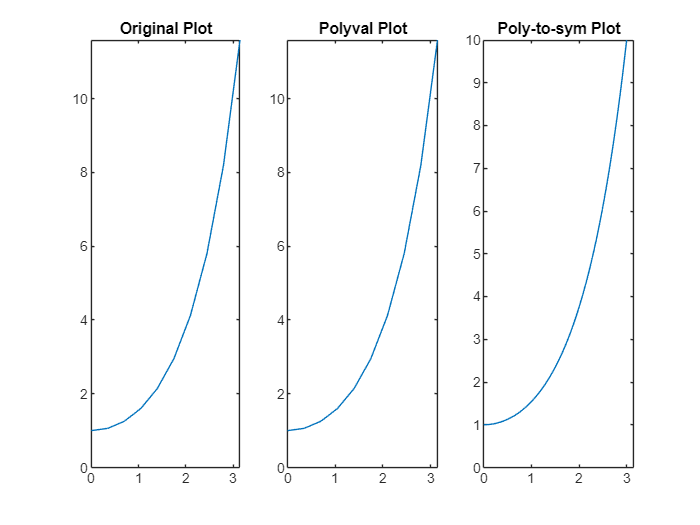


subplot(1,3,1), plot(x, y)
    title("Original Plot")
    xlim([min(x) max(x)]), ylim([0 max(y)])

N = length(x);
p = polyfit(x, y, N-1);

% Versione con polyval
polInt = polyval(p, x);

subplot(1,3,2), plot(x, polInt);
    title("Polyval Plot")
    xlim([min(x) max(x)]), ylim([0 max(y)])

% versione con poly2sym
polIntSym = poly2sym(p);

subplot(1,3,3), fplot(polIntSym, [min(x) max(x)]);
    title("Poly-to-sym Plot")
    xlim([min(x) max(x)]), ylim([0 max(y)])